**Motor Calibration**

We are trying to solve for coefficients needed in M(s) motor control block, given as M(s) = V(s)/Vc(s) = K/tau / (s + 1/tau), where V(s) is the velocity of each wheel, and Vc(s) is the velocity control signal coming from the PI controller K(s). 

The motor input signal we gave to collect this calibration data was a step input with a constant magnitude of 300. 

In the time domain V(s) is v(t) = 300*K*(1-exp(-t/tau)) and we can fit the collected speed data for the right and left wheel to this function. Units of axes are speed [m/s] and time [s].

Relating this form of M(s) to another form of writing M(s) = a*b/(s + a), b = K and a = 1/tau.

% data = [PASTE DATA HERE];
% speed_left = data(:,1)
% speed_right = data(:,2)
% time = linspace(0, 3000, 3000/20+1)'
% time = time(:, 1:141) / 1000; % shorten to match speed data, convert ms to s
% save("motor_calibration_data", "speed_left", "speed_right", "time")

load("motor_calibration_data")

velocity_left = velocity_fit(time, speed_left);

Unrecognized function or variable 'time'.

title("Left Motor Calibration Data");
K_left = velocity_left.K
tau_left = velocity_left.tau

velocity_right = velocity_fit(time, speed_right);

Unrecognized function or variable 'time'.

title("Right Motor Calibration Data");
K_right = velocity_right.K
tau_right = velocity_right.tau

**Gyro Calibration**

% gyro_angle = [PASTE DATA HERE];

% length(gyro_angle(:,1))
% for i = 1:length(gyro_angle(:,1))
%     if gyro_angle(i,1) < 0
%         gyro_angle(i,1) = gyro_angle(i,1) + 3.14;
%     end
% end
% gyro_angle
 
time = linspace(0, 7750, 7750/50+1)';
time = time(1:155, :) / 1000; % shorten to match speed data, convert ms to s
save("gyro_calibration_data2", "gyro_angle", "time")

Calculate natural frequency based on swinging pendulum freely and collecting angle measurements; should follow sinusoidal shape. To measure period get the time between peaks, then convert that into natural frequency in radians per second. 

Find the effective length of the pendulum using natural frequency omega = sqrt(g/l), rearranged to find effective length l = g/omega^2. 

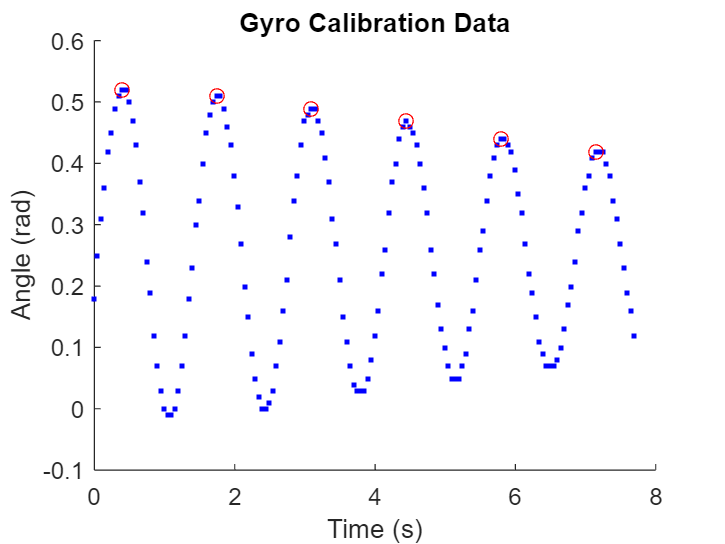

load("gyro_calibration_data2")

clf; hold on;
plot(time, gyro_angle, "b.")
ylabel('Angle (rad)')
xlabel('Time (s)')
title("Gyro Calibration Data")

[angle, t] = findpeaks(gyro_angle, time);
plot(t, angle, "ro");


delta_t = t(2:end)-t(1:end-1);
avg_period = mean(delta_t) % period [s]

avg_period = 1.3500

f = 1/avg_period % frequency [Hz = 1/s]

f = 0.7407

omega = 2*pi*f % natural frequency [rad/s]

omega = 4.6542

g = 9.81; % m/s^2
effective_length = g/omega^2 % effective length [m]

effective_length = 0.4529

function [fitresult, gof] = velocity_fit(time, speed)
%  Create a fit.
%
%  Data for 'velocity_fit' fit:
%      X Input: time
%      Y Output: speed
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.

%% Fit: 'velocity_fit'.
[xData, yData] = prepareCurveData( time, speed );

% Set up fittype and options.
ft = fittype( '300*K*(1-exp(-t/tau))', 'independent', 't', 'dependent', 'v' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.002 60/1000];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'velocity_right2_fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Velocity vs. Time', 'Velocity Fit', 'Location', 'NorthEast', 'Interpreter', 'none' );

% Label axes
xlabel( 'Time (s)', 'Interpreter', 'none' );
ylabel( 'Velocity (m/s)', 'Interpreter', 'none' );
grid on

end